# Tutorial 2: Applying the Algorithm Selection Rule

## 1. Objectives

In this tutorial, we will demonstrate how to apply the algorithm selection rule introduced in the paper. It will cover:

- Loading data

- Applying the algorithm selection rule

- Selecting an optimal algorithm

In the first tutorial, we showed how to (1) generate a dataset consisting of burst-embedded synthetic neural signals, (2) apply different burst detection algorithms, and (3) compute performance metrics and organize them into heatmaps. Using the simulation results provided in the GitHub repository, we will now discuss how to select an algorithm that will perform optimally for a user-specific dataset.

*** Note: We recommend using the `Output inline` mode for better visualizations of the tutorial across different screen sizes.

### (A) Motivations

The basic idea behind the algorithm selection rule is that we estimate how likely each algorithm will perform on a real dataset based on its performance on the simulated dataset. After algorithms are applied to the data, we match their burst detections to simulated bursts based on their length and noise level. For each simulated burst of specific duration and noise level, we already have a corresponding performance metric that indicates how confident each algorithm is in detecting a burst having these specific characteristics (refer to **Tutorial 1**). Therefore, from these sets of matched simulated bursts, we can derive a distribution of performance metrics for each algorithm and select the best one by comparing these distributions.

The schematics and procedures of implementing the selection rule can be found in **Figure 5** of our paper.

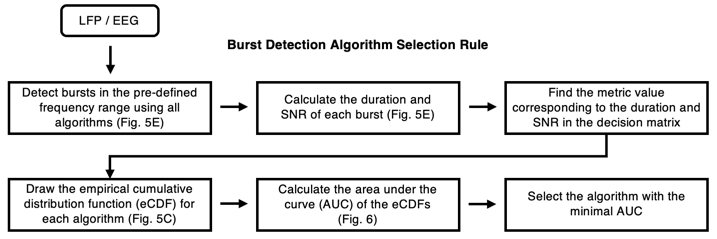 **Figure 5A**

**Example**

To illustrate this idea with an example, let's say we chose detection confidence as our performance metric and multitaper (MTP) method as our algorithm. Once we detect bursts from some experimental data using MTP, we can map its detections to simulated bursts by comparing the duration and signal-to-noise ratio (SNR) of the bursts. If a beta burst detected by MTP had a duration of 240 ms (i.e., 6 cycles) with a noise level of 4 dB, we know that MTP had a detection confidence score of 0.67 from the simultaion result. We repeat this for all the bursts detected by MTP, resulting with a vector of confidence scores. Having such vector of mappings, we can now plot the empirical cumulative density function (eCDF) and compute its AUC. We repeat this process for every algorithm we want to compare. Finally, we can compare the AUC of MTP for this particular experimental data to that of other algorithms. The algorithms with the lowest AUC will be determined as optimal, because the low AUCs indicate that the distribution of metric values had more higher confidence scores than lower scores (see ***Materials & Methods***).

## 2. Loading Simulation Results and Real Datasets

As explained above, we need both simulated results and experimental data to employ our algorithm selection rule and gauge which algorithm is most likely to perform best. First, let's begin by loading the functions we need for this tutorial.

util_path = genpath("../utils");
addpath(util_path);

### (A) Loading simulation results

**Tutorial 1** showed you how heatmaps containing different performance metric values can be saved as a `.mat` file. In this tutorial, we will load the simulation results provided by the paper (in particular, the heatmaps for gamma burst detection).

band_name = 'gamma';
HEATMAP = load(['../data/simulation_data/HM_' band_name '.mat']).HEATMAP;
DET_CONF = load(['../data/simulation_data/DC_' band_name '.mat']);
scoreMat = {
    struct2cell(HEATMAP.precision)';
    struct2cell(HEATMAP.recall)';
    struct2cell(HEATMAP.f1_score)';
    struct2cell(HEATMAP.concurrence)';
    DET_CONF.detection_confidence
};
metric_names = {'Precision','Recall','F1-Score','Temporal Concurrence','Detection Confidence'};
method_names = {'BP','ENV','S-STFT','MTP','CWT'};
nMethod = length(method_names);

### (B) Loading a real dataset

For the experimental dataset, we will use the escape paradigm dataset (Kim et al., 2020; refer to the paper for the full reference and further details). The data contains LFP activities measured from the basolateral amygdala (BLA), prefrontal cortex (PFC), and hippocampus (HPC) over 64 trials. Here, we will use a subset of BLA LFP signals (n=16 trials).

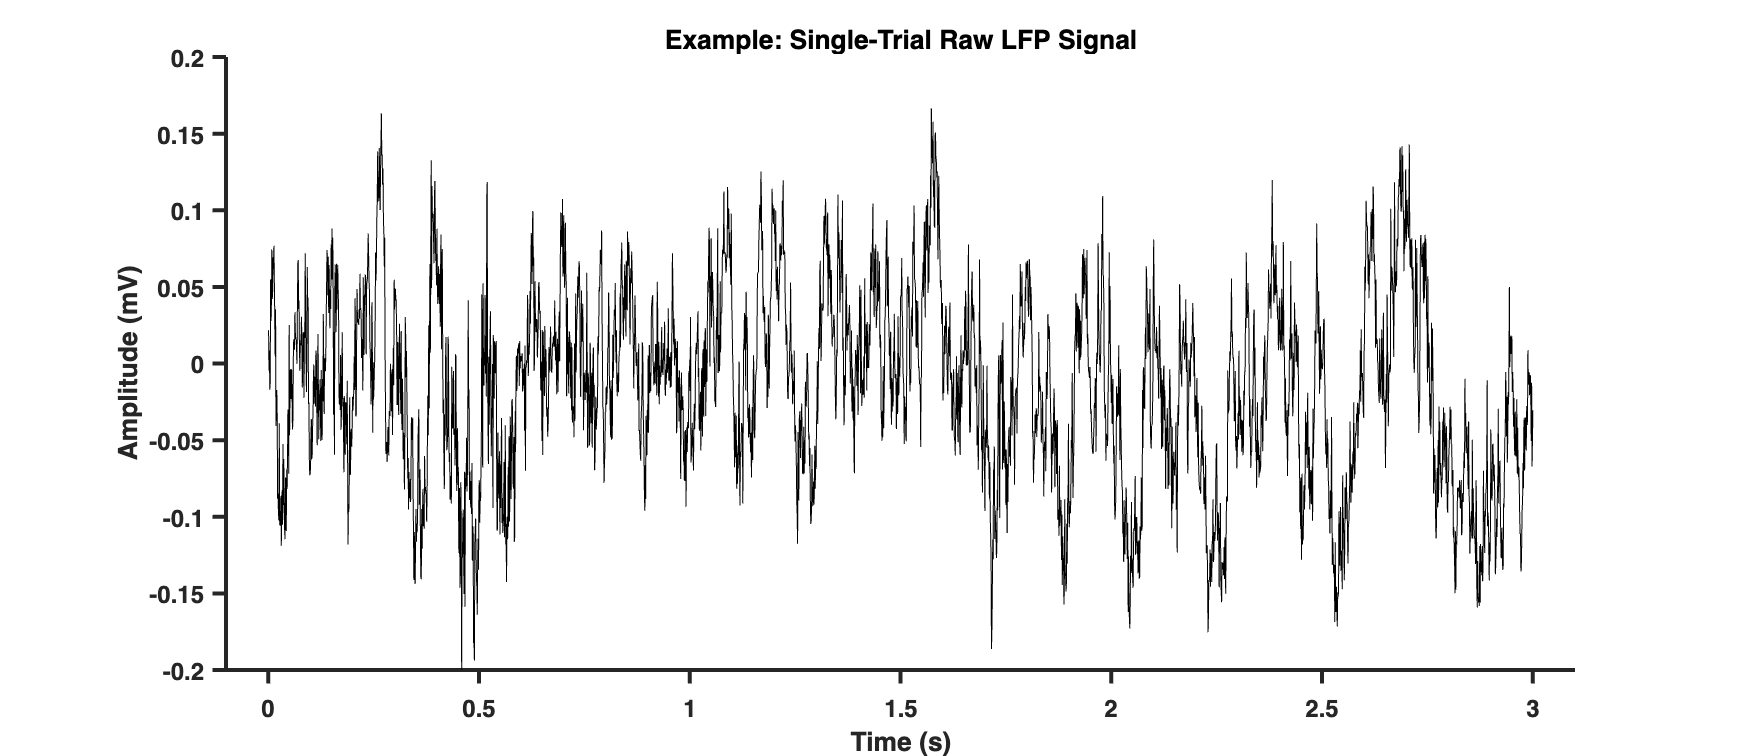

% Add Path to Experimental Data
data_path = genpath('../data/experimental_data/ESCAPE');
addpath(data_path);

% Load Real Dataset
load('lfps/escape_eeg_all.mat');
anatomy_idx = 1;                          % 1-BLA; 2-PFC; 3-HPC
Fs = srate;                               % sampling rate
Nyq = Fs/2;                               % Nyquist frequency
tvec = times;                             % time vector
nTrial = size(data,3);                    % total number of available trials
signals = squeeze(data(anatomy_idx,:,:)); % LFP neural signals

% Select Trials of Interest
sel_trials = sort(cat(2,1:8:nTrial,5:8:nTrial)); % 1st trials of Day 1 & Day 2 for 8 mice
nSelTrial = length(sel_trials); % number of selected trials

% Plot Real Data
figure();
ex_signal = signals(:,1);
plot(tvec(1:Fs*3),ex_signal(1:Fs*3),'Color','k');
xlabel('Time (s)')
ylabel('Amplitude (mV)')
title('Example: Single-Trial Raw LFP Signal')
set(gca,'FontSize',12,'FontWeight','bold','LineWidth',2,'TickDir','Out','Box','Off','XLim',[-0.1, 3.1]);
set(gcf,'Position',[476,494,870,378]);

#### Relevant Scripts

- `Figure5/fig5C_compute_ecdf.m`

## 3. Applying the Algorithm Selection Rule

### (A) Detecting Bursts from Experimental Data

Having data and simulation results ready, we can now move onto selecting the best algorithm. To do so, we first need to apply all the burst detection algorithms to our dataset. As discussed in **Tutorial 1**, each algorithm requires its own unique set of hyperparameters.

#### [i] Set Hyperparameters for Each Algorithm

% Time Domain
lo_f = 35; % lower frequency bound
hi_f = 45; % upper frequency bound
mid_f =  (lo_f + hi_f) / 2;

% Time-Frequency Domain
freq_range = unique([15:5:30 30:10:70 70:15:100]); % frequencies of interest
dt = 0.01;                                         % time step for sliding windows
nOscCycle_stp = 6; nOscCycle_mtp = 6;              % frequency-dependent window size
nw = 2; ntp = 3;                                   % DPSS slepian sequences
wname = 'amor'; scale_opt = 'default';             % type of and scaling option for the wavelet
interp_opt = false;
check_opt = true;
plot_psd = false;
plot_tp = false;
verbose = false;

% Amplitude Thresholds
thrA_factor = 2.5;       % for bandpass filtering method
prcthrA = 95;            % for envelope-based method
specthrA_factor = 1.8;   % for spectral analysis methods

% Window Time Steps
dt_stp = dt;
dt_mtp = dt;
dt_cwt = 1/Fs;

#### [ii] Apply Burst Detection Algorithms

After setting necessary hyperparameters, we can apply the algorithms to the experimental data and detect bursts.

% Preallocate Cell Array for Storing Burst Onsets and Offsets for Each Trial
BT = cell(1,nSelTrial);

% Detect Bursts
hp = helper;
for n = 1:nSelTrial
    % Get LFP Data
    signal = double(signals(:,sel_trials(n))');
    % Apply IIR Notch Filter
    w0 = 60/Nyq;
    q_factor = 35;
    bw = w0/q_factor;
    [b,a] = iirnotch(w0,bw);
    signal = filtfilt(b,a,signal);
    % Apply Bandpass Filtering (BP)
    filt_sig = eegfilt(signal,Fs,lo_f,hi_f);
    [btime_bp,burst_bp] = detect_burst_timeseries(Fs,tvec,filt_sig,lo_f,hi_f,thrA_factor);
    % Apply Amplitude Envelope (ENV)
    [btime_ev,burst_ev,~] = detect_burst_ampenv(Fs,tvec,filt_sig,lo_f,hi_f,prcthrA);
    % Apply Single-Tapered Short Time Fourier Transform (S-STFT)
    [Spec_f_stp,Spec_t_stp,Spec_stp,~] = spectrogram_stp(tvec,signal,Fs,freq_range,dt_stp,nOscCycle_stp,verbose,interp_opt);
    [btime_stp,burst_stp,~] = detect_burst_spectrogram(Spec_f_stp,Spec_t_stp,Spec_stp,dt_stp,specthrA_factor,verbose);
    minIdx_stp = find(abs(Spec_f_stp-mid_f) == min(abs(Spec_f_stp-mid_f)));
    [btime_stp,burst_stp] = extract_single_freqband(btime_stp,burst_stp,minIdx_stp);
    % Apply Multitaper Spectrogram (MTP)
    [Spec_f_mtp,Spec_t_mtp,Spec_mtp,~] = spectrogram_mtp(tvec,signal,Fs,nw,ntp,freq_range,dt_mtp,nOscCycle_mtp,interp_opt,plot_psd,check_opt,plot_tp,verbose);
    [btime_mtp,burst_mtp,~] = detect_burst_spectrogram(Spec_f_mtp,Spec_t_mtp,Spec_mtp,dt_mtp,specthrA_factor,verbose);
    minIdx_mtp = find(abs(Spec_f_mtp-mid_f) == min(abs(Spec_f_mtp-mid_f)));
    [btime_mtp,burst_mtp] = extract_single_freqband(btime_mtp,burst_mtp,minIdx_mtp);
    % Apply Continuous Wavelet Spectrogram (CWT)
    [wav_freq,wav_time,Spec_cwt,~] = spectrogram_cwt(tvec,signal,Fs,wname,scale_opt,verbose);
    [btime_cwt,burst_cwt,~] = detect_burst_spectrogram(wav_freq,wav_time,Spec_cwt',dt_cwt,specthrA_factor,verbose);
    minIdx_cwt = find(abs(wav_freq-mid_f) == min(abs(wav_freq-mid_f)));
    [btime_cwt,burst_cwt] = extract_single_freqband(btime_cwt,burst_cwt,minIdx_cwt);
    % Only Keep Bursts from Experiment Stage 2
    BT{n} = hp.pack_data(parse_data(btime_bp),parse_data(btime_ev), ...
        parse_data(btime_stp),parse_data(btime_mtp),parse_data(btime_cwt));
end
dtMat = hp.pack_data(1/Fs, 1/Fs, dt_stp, dt_mtp, dt_cwt);

### (B) Computing eCDF and its AUC

Now, for each algorithm, we map its burst detections to their corresponding performance metrics values extracted from the simulated results based on their burst duration and noise level. Then, we compute the AUC of the eCDF built from a set of performance scores. This procedure can be executed with the function `compute_ecdf_auc`. 

Here, we plot a raster plot of bursts detected from a single trial to qualitatively demonstrate performances of different algorithms. For the same trial, we also graph eCDFs of the algorithms and report their AUC, using detection confidence as a chosen performance metric.

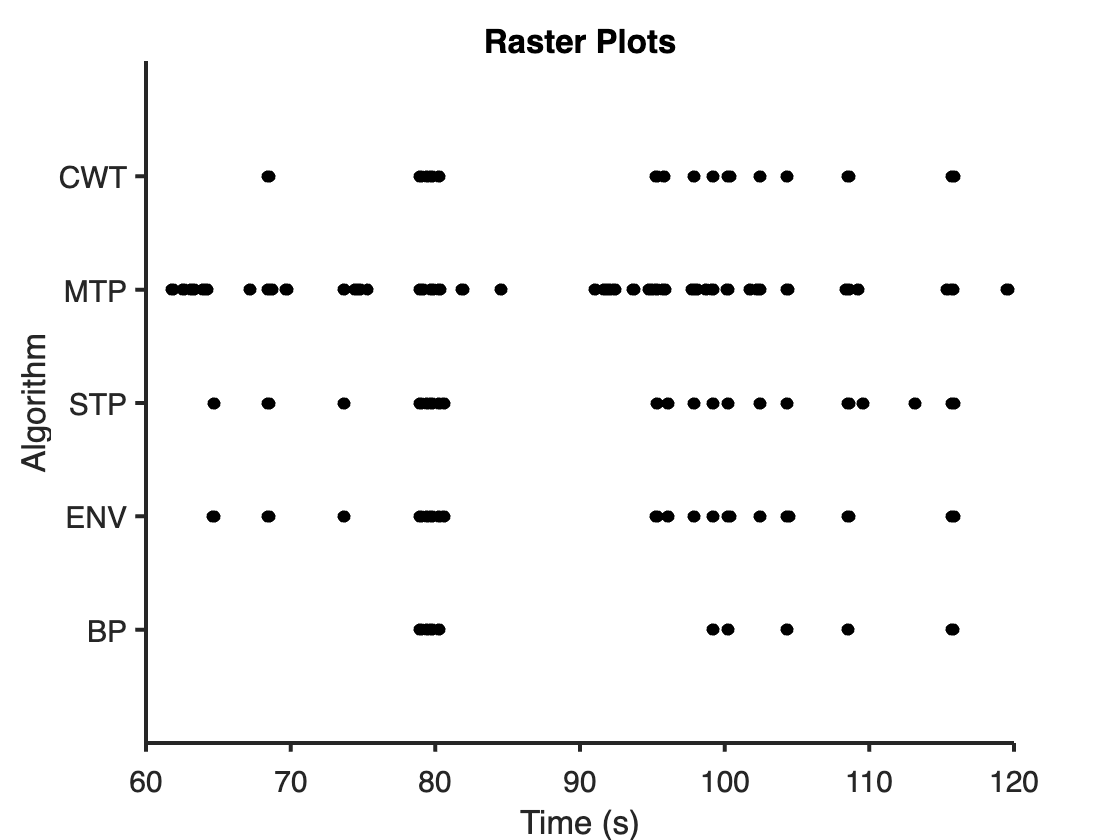

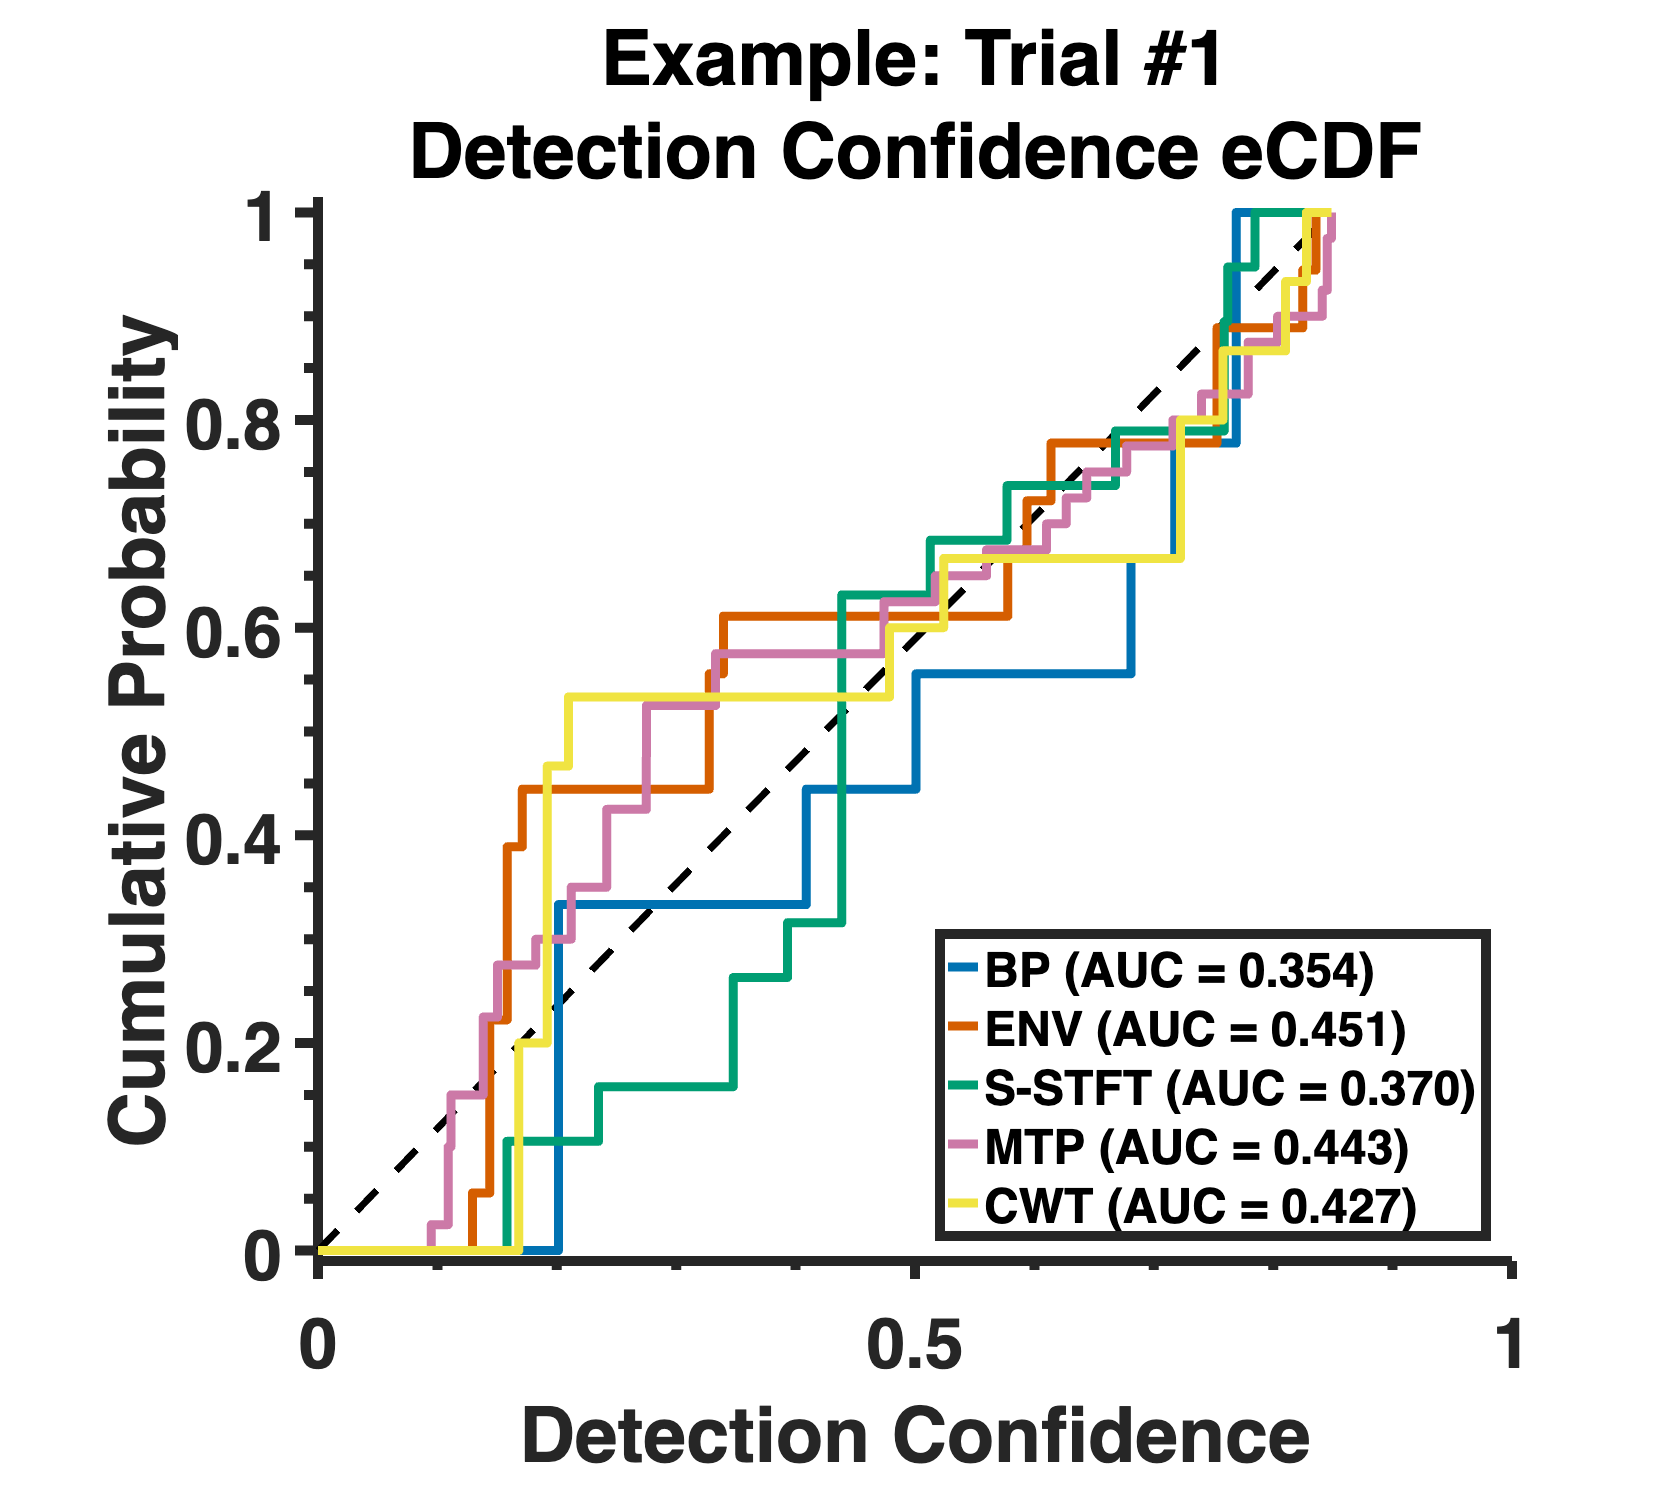

Processed: 4/16 trials 
Processed: 8/16 trials 
Processed: 12/16 trials 
Processed: 16/16 trials 


% Preallocate Arrays for Storing AUCs
AUC = struct();
[AUC.precision, AUC.recall,AUC.f1_score,AUC.concurrence,AUC.detection_confidence] = deal(zeros(nSelTrial,nMethod));

% Compute eCDF and its AUC
for n = 1:nSelTrial
    signal = double(signals(:,sel_trials(n))'); % get LFP data
    indicator = {'precision','recall','f1_score','concurrence','detection_confidence'};
    for m = 1:length(scoreMat)
        if n == 1 && m == length(scoreMat)
            verbose_cdf = true;
        else; verbose_cdf = false;
        end
        [bscoreMat,auc] = compute_ecdf_auc(sel_trials(n),metric_names{m},scoreMat{m},BT{n},dtMat, ... 
                           tvec,signal,Fs,lo_f,hi_f,verbose_cdf);
        AUC.(indicator{m})(n,:) = auc;
    end
    if mod(n,4) == 0
        fprintf(['Processed: ' num2str(n) '/' num2str(nSelTrial) ' trials \n']); % report progress
    end
end

From the eCDFs, we can conclude that BP has the lowest AUC and is thus estimated to be the best algorithm for detecting bursts in Trial #1. The algorithm is said to be optimal for a particular dataset if it has the lowest AUC, because it indicates that the distribution of performance metrics contains more detections with higher metric scores, leading to steeper increase in cumultiave probabilities at the higher end of the detection confidence value range (see **Section 1**).

#### Relevant Scripts

- `Figure5/fig5C_compute_ecdf.m`

## 4. Selecting the Best Algorithm

The algorithm selection process discussed above was limited to a single trial. To determine the best algorithm for an entire dataset, we have to probe the distributions of the algorithmic performances for all trials we are interested in.

% Choose Performance Metric
metric = 'detection_confidence';
metric_name = 'Detection Confidence';
auc = AUC.(metric);
algorithms = {'BP','ENV','S-STFT','MTP','CWT'};
nMethod = length(algorithms);
fprintf(['\n* Selected Metric: ' upper(metric) '\n']);


* Selected Metric: DETECTION_CONFIDENCE


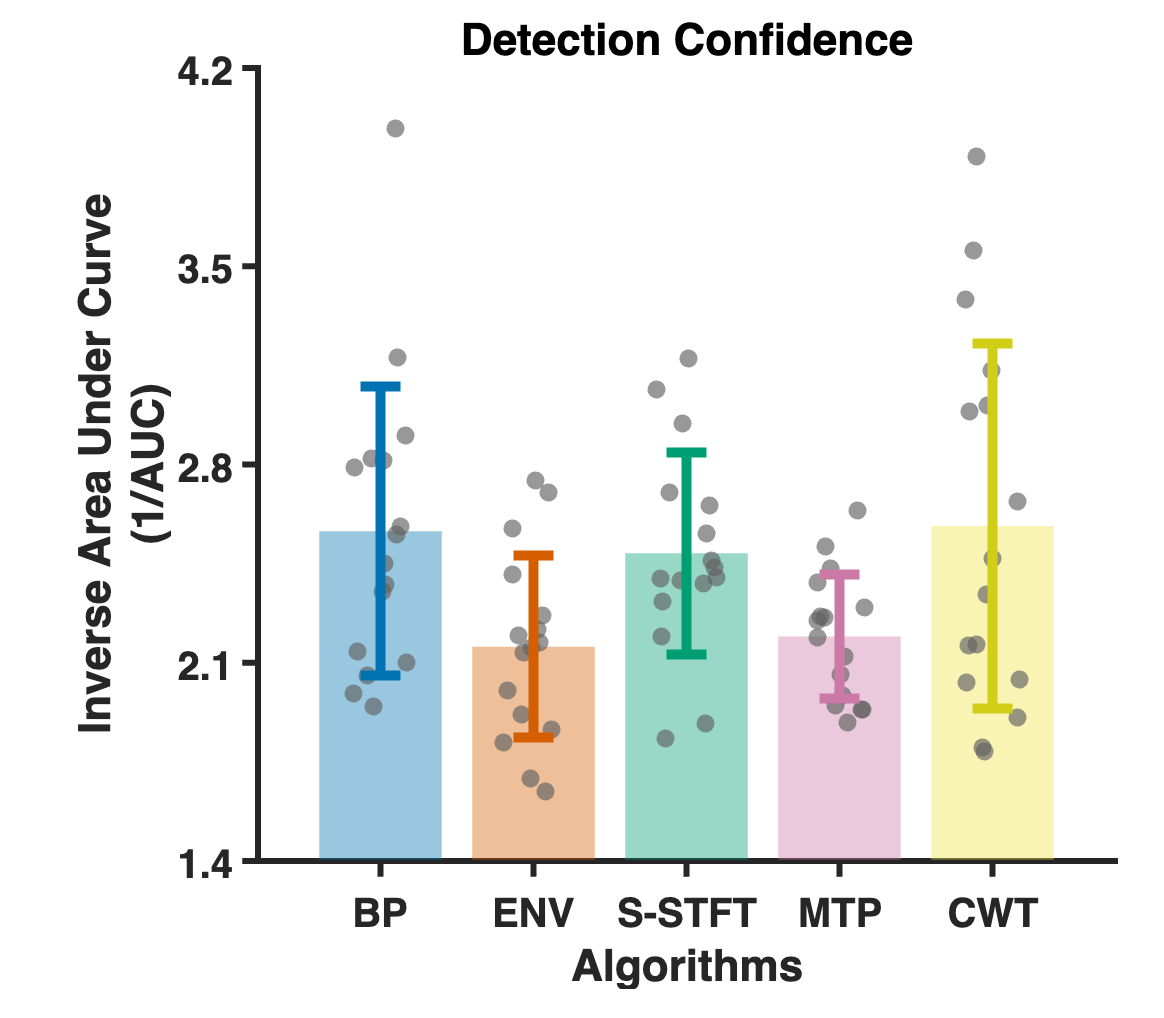

% Compute Inverse AUC and Its Statistics
inverse_auc = 1./auc;
auc_mean = mean(inverse_auc,1,'omitnan');
auc_std = std(inverse_auc,1,'omitnan');
nSelTrial = size(inverse_auc,1);

% Set Visualization Parameters
okabe_ito = [[0,114,178];
             [213,94,0];
             [0,158,115];
             [204,121,167];
             [240,228,66]]./255;
grey = [97,97,97]./255;
vmin = round(min(inverse_auc, [], 'all'),1)-0.1;
vmax = round(max(inverse_auc, [], 'all'),1)+0.1;
if mod(vmin,0.2) ~= 0
    vmin = vmin - 0.1;
end
if mod(vmax,0.2) ~= 0
    vmax = vmax + 0.1;
end
alpha = 0.4;

% Plot Inverse AUC across Trials
figure(); hold on;
x_axis = 1:nMethod;
b = bar(x_axis, auc_mean);
b.FaceColor = 'flat';
for n = 1:nMethod
    b.CData(n,:) = okabe_ito(n,:);
end
s = cell(size(x_axis));
for n = 1:nMethod
    rnd = unifrnd(-0.2,0.2,1,nSelTrial);
    s{n} = scatter(ones(1,nSelTrial)*n+rnd,inverse_auc(:,n),80,grey,'filled');
    s{n}.MarkerFaceAlpha = 0.65;
    s{n}.LineWidth = 1.5;
end
er = cell(size(x_axis));
for n = 1:nMethod
    er{n} = errorbar(x_axis(n),auc_mean(n),auc_std(n),auc_std(n));
    er{n}.Color = okabe_ito(n,:);
    if n == nMethod
        er{n}.Color = [209,206,23]./255; % darker yellow for visibility
    end
end
xticks(x_axis);
xticklabels(algorithms);
yticks(linspace(vmin,vmax,5));
xlim([0.2,nMethod+0.8]);
ylim([vmin,vmax]);
xlabel('Algorithms');
ylabel({'Inverse Area Under Curve'; '(1/AUC)'});
title('Detection Confidence');
set(b,'EdgeColor','none','BaseValue',vmin+0.004,'ShowBaseLine','off','FaceAlpha',alpha);
set([er{:}],'CapSize',20,'LineStyle','none','LineWidth',5);
set(gca,'FontSize',20,'LineWidth',3,'TickDir','out','TickLength',[0.015, 0.025],'XTickLabelRotation',0,'Box','off','FontWeight','bold',...
    'Position',[0.2216,0.1545,0.7362,0.7784]);
set(gcf,'Color','w','Position',[453,327,582,509]);

The resulting plot reports that CWT have the highest mean$AUC^{-1}$ values, although its difference between BP and S-STFT is marginal (see **Fig. 6** for details). To quantitiatively evaluate such differences, we conduct statistical tests on computed inverse AUC values. In our study, we used One-Way ANOVA to check if all group means are identical to one another. Then, to further test if there is a significant pair-wise difference between two group means (i.e., algorithms), we used Tukey-Kramer method to correct the multiple comparisons probelm based on a studentized range distribution.

% One-Way ANOVA
group = algorithms;
[p,tbl,stats] = anova1(inverse_auc,group,'off');

% Multiple Comparisons Test: Tukey's HSD
[c,m_est,~,gnames] = multcompare(stats,'CType','tukey-kramer','Display','off');
mc_tbl = array2table(c,'VariableNames',{'Group','Control Group','Lower Limit','Difference','Upper Limit','p-value'});
mc_tbl.('Group') = gnames(mc_tbl.('Group'));
mc_tbl.('Control Group') = gnames(mc_tbl.('Control Group'));

% Print Statistical Test Summary
view = true;
if view
    fprintf('* One-Way ANOVA with HSD (multiple comparisons test): \n');
    disp(mc_tbl);
end

* One-Way ANOVA with HSD (multiple comparisons test): 


      Group       Control Group    Lower Limit    Difference    Upper Limit    p-value 
    __________    _____________    ___________    __________    ___________    ________

    {'BP'    }     {'ENV'   }       -0.038147       0.40802       0.85418      0.089269
    {'BP'    }     {'S-STFT'}        -0.36828      0.077879       0.52404       0.98826
    {'BP'    }     {'MTP'   }       -0.074542       0.37162       0.81778       0.14746
    {'BP'    }     {'CWT'   }        -0.46445     -0.018285       0.42788       0.99996
    {'ENV'   }     {'S-STFT'}         -0.7763      -0.33014       0.11603       0.24466
    {'ENV'   }     {'MTP'   }        -0.48256     -0.036395       0.40977       0.99939
    {'ENV'   }     {'CWT'   }        -0.87246       -0.4263      0.019863      0.068061
   

As seen from the table above, we can see that CWT does not show signiciant differences against other four algorithms. Therefore, we conclude that although CWT is the best performing algorithm with a highest detection confidence for this dataset, its performance is not significantly different from other algorithms. The statistical test suggests that all classic burst detection algorithms discussed in the paper perform at a similar level and therefore require further improvements. For extended interpretations, please refer to ***Discussion***.

#### Relevant Scripts

- `Figure6/fig6A_C_algorithm_selection.m`

## 5. Appendix

#### In-Script Functions

function [btime] = parse_data(btime)
    idx = cellfun(@(b) b(1) >= 60 && b(end) <=120, btime);
    btime = btime(idx);
end